### Exercise 1. Construct an input space consisting of the polynomials x0, x1, x2, x3, and x4 evaluated over the range [–1,1]. Then generate a weighted sum of these polynomials using random weights (e.g. randn). Repeat this a total of 20 times and visualize the results.

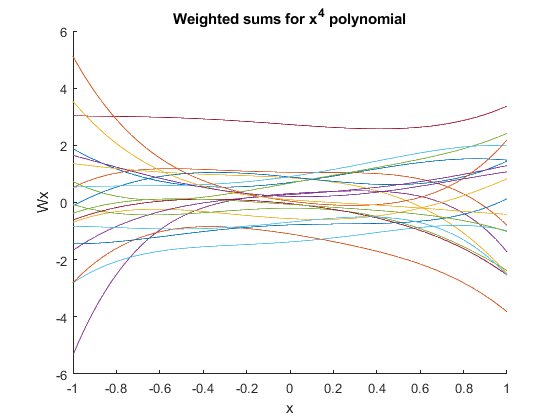

repeatCount = 20;
ppower = 5;
x = -1:0.01:1;

w = randn(20, ppower);

figure;
hold on;
xlabel('x');
ylabel('Wx');
title(sprintf('Weighted sums for x^%d polynomial', ppower-1));
for i = 1 : repeatCount
    plot(x, polyval(w(i,:), x));
end
hold off;

### Exercise 2: Generate some random data using rand(1,100).^4. We want to find a value that summarizes the central tendency of these data, and suppose we have chosen the error metric of the sum of the absolute differences between the value and the data points. Plot the error surface, i.e. a function that illustrates the relationship between candidate values and the error associated with these values. For the candidate values, use 100 equally spaced values between 0 and 1 (e.g. linspace(0,1,100).

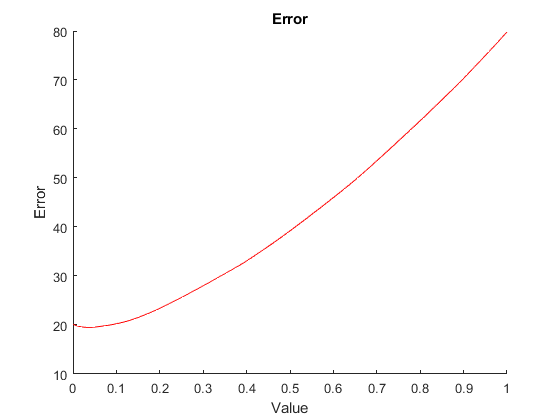


data = rand(1, 100).^4;

space = linspace(0, 1, 100);
errors = sum(abs(data(:) - space));

figure; hold on;
title('Error');
xlabel('Value');
ylabel('Error');
plot(space, errors, 'r-');
hold off;

### Exercise 3: Generate some random data using x = rand(1,1000); y = x+0.1*randn(1,1000);. Using ordinary least-squares (OLS), fit a line to these data and visualize the results.

x = rand(1, 1000);
y = x + .1 * randn(1, 1000);

X = [x(:) ones(length(x), 1)];

w = inv(X'*X) * X' * y(:);

fprintf('a : %f, b: %f \n', w(1), w(2)); 

a : 0.989543, b: 0.004458 


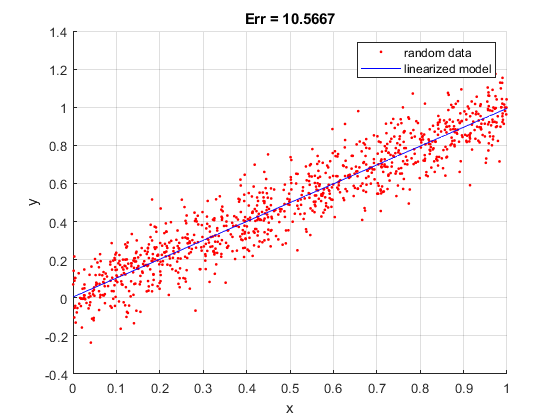


model = X * w;

sqErr = sum((y' - model).^2);

figure;
hold on;
scatter(x, y, 'r.');
ax = axis;

xM = linspace(ax(1), ax(2), 100)';
yM = [xM ones(length(xM), 1)] * w;
plot(xM, yM, 'b-');
grid;
legend('random data', 'linearized model');
xlabel('x');
ylabel('y');
title(sprintf('Err = %.4f', sqErr));
hold off;

### Exersise 4: Consider the model y=ax+b. Using a= 1.3 and b= 1, generate some simulated data. Then use nonlinear optimization to fit the model to the data. For a visualization of the search process, download the file outputfcnplot.m and pass the options structure optimset('Display','iter','OutputFcn' @(a,b,c) outputfcnplot(a,b,c,1,y)) to the optimizer (e.g.lsqnonlin.m). (Note that the options structure code assumes that y is defined in the workspace and refers to the simulated y-values.)


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality


     0          3         27270.8                      1.13e+04


     1          6           26439        0.48664       7.65e+03      


     2          9         26058.5      0.0699821            459      


     3         12         26057.3       0.016974           26.7      


     4         15         26057.2     0.00738439           8.02      


     5         18         26057.2     0.00170282           1.08      


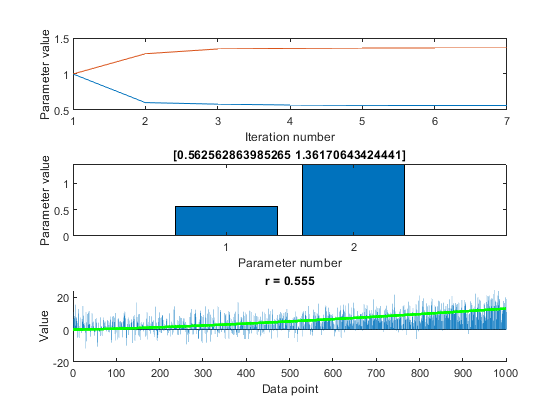


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the selected value of the function tolerance.

<stopping criteria details>



a = 1.3;
b = 1;

% generate random data
xx = 0:.01:10;
yy = a.^xx + b + 5 * randn(size(xx));

% we have to fit a model to the generated data

% define optimization options
options = optimset('Display', 'iter', 'FunValCheck', 'on', ...
    'MaxFunEvals', Inf, 'MaxIter', Inf, ...      
    'TolFun', 1e-6, ...
    'OutputFcn', @(a,b,c) outputfcnplot(a,b,c,1,yy));
 
% define bounds for the parameters
%            a       n
paramslb = [0.0     0.0];    % lower bound
paramsub = [inf     inf];   % upper bound

% define the initial seed
%          a       n
params0 = [1.0    1.0];


model = @(pVect, xVect) pVect(1) * xVect.^pVect(2);

% output the predicted values
[params, resnorm, residual, exitflag, output] = ...
    lsqcurvefit(model, params0, xx, yy, paramslb, paramsub, options);

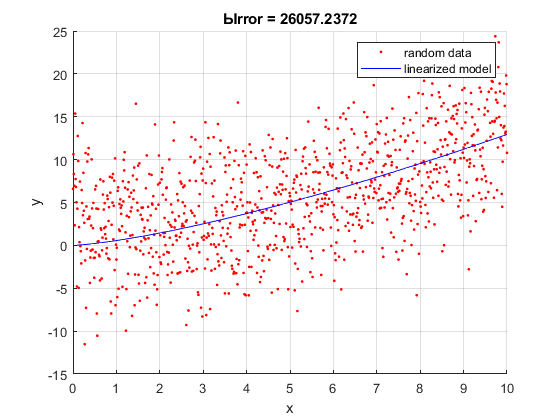



% define the model using weights
yyModel = model(params, xx);

% calculate the squared error, achieved by the yModel
% resnorm = value of squared error
sqErrModel = sum((yy' - yyModel').^2);

% visualize
figure; hold on;
grid;
scatter(xx, yy, 'r.');
% save current axis (for x and y axes)
axM = axis;

% get limits for x ax, divide the interval into 100, convert to column
xxM = linspace(axM(1), axM(2), 100)';
yyM = modelfun(params, xxM);
plot(xxM, yyM, 'b-');
legend('random data', 'linearized model');
xlabel('x');
ylabel('y');
title(sprintf('Ыrror = %.4f', resnorm));

### Exercise 5: Implement one-dimensional nearest-neighbor regression. To do this, first write a function that conforms to the declaration given below. Then, generate and visualize some data (x-and y-values). Finally, calculate the prediction of the nearest-neighbor regression model for the range of x-values shown in the plot and visualize the results.

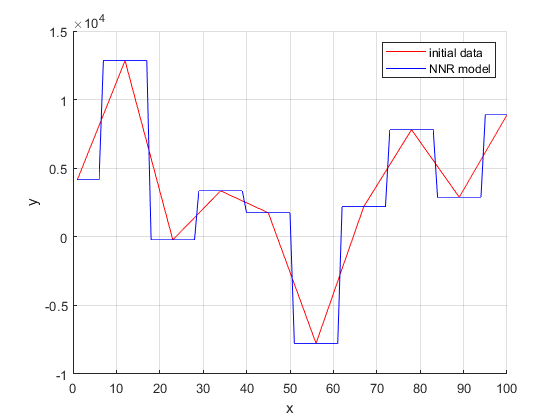

%{
function yy = nnregress(xx,x,y) 
<xx> is a vector of x-coordinates to evaluate at 
<x> is a vector of x-data 
<y> is a vector of y-data 
%return a vector with the predictions of a 
nearest-neighbor regression model evaluated 
at the values in <xx>. 
%}

xNNR = linspace(1, 100, 10);
yNNR = xNNR.^2 + xNNR + 5000 * randn(1, length(xNNR));

% visualize the generated data
figure;
hold on; grid;
xlabel('x');
ylabel('y');
plot(xNNR, yNNR, 'r-');

% generate vector of xx and visualize the result of NNR model
xxNNR = linspace(1, 100, 100);
yyNNR = nnregress(xxNNR, xNNR, yNNR);
plot(xxNNR, yyNNR, 'b-');
legend('initial data', 'NNR model');


% the nnregress function for each xx' value in xx we will find the nearest
% pair (x', y') from (x, y) according to the nearest distance between xx'
% and x'
% x'min = min_distance(x,xx');


function yy = nnregress(xx, x, y)
    yy = zeros(1, length(xx));
    for i = 1 : length(xx)
        distances = abs(xx(i) - x);
        index = distances == min(distances);
        
        % return the corresponding yy values (get from y by index)
        yy(i) = y(index);
    end
end